Bewegung der MHT Einheit

Bereich der Kollisionsfrein bewegung

figure(1)
% motionfield
mf= [0 0 0   NaN NaN; ...
            10 -5 20  NaN NaN; ...
            20 -10 30  NaN NaN; ...
            30 -20 40 0 0; ...
            40 -30 30  -10 20; ...
            50 -40 35  -15 10; ...
            60 -30 40   -5 5 ; ...
            70 -60 60   -30 30; ...
            80 -70 50 0 0; ...
            90 -60 55 NaN NaN; ...
            100 -50 50 NaN NaN];
plot(mf(:,1),mf(:,[2,3, 4, 5]),'b*' )
hold on
~isnan(mf(:,4));
xx = 0:1:100;
x=mf(:,1)

x =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


for i=2:3
y =mf(:,i);
yy = spline(x,y,xx);
plot(xx,yy,'b' )
end
xx = 30:80;
for i=4:5
x=mf(~isnan(mf(:,4)),1);
y=mf(~isnan(mf(:,4)),i);
yy = spline(x,y,xx);
plot(xx,yy,'b' )
end 
grid on
hold on


Gnerate random Pos

n=0;
x=rand()*100;
y=rand()*200-100;
while ~inArea(mf, x,y)
    x=rand()*100;
    y=rand()*200-100;
    if n>100
        break 
    end
        n=n+1; 
  
end
    plot(x,y,'ro')
    xlabel('\theta 1')
    ylabel('\theta 2')
    title('Allowed Areas')
    
    
   

    

Find Path home

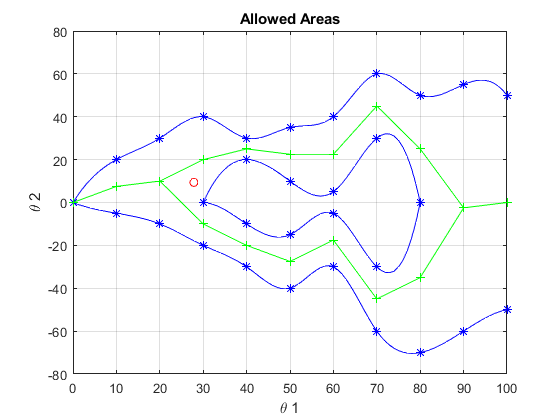

   p=zeros(size(mf,1),2);
    for i=1:size(mf,1)
       if isnan(mf(i,4)) 
         p(i,:)= [(mf(i,2)+mf(i,3))/2, (mf(i,2)+mf(i,3))/2];
        else
         p(i,:)= [(mf(i,2)+mf(i,4))/2 , (mf(i,3)+mf(i,5))/2];
        end
     end
     plot(mf(:,1),p,'g')
     plot(mf(:,1),p,'g+')
     
 
 
     hold off

Prüft ob punkt im Feld

function b = inArea(mf, x,y)
% find index
in = ceil( x/10);
b1 = ( y> mf(in,2) && y<(mf(in,3)));
b2=    (y< mf(in,4) || y>(mf(in,5)));
b= b1 && (isnan(mf(in,4)) || b2) ;  
end